close("all"); clear; clc;
setmadsympath;

t = sym('t');
N = Frame;
O = Point;

yaw = DynamicVariable("psi");
camber = DynamicVariable("gamma");
pitch = DynamicVariable("theta");
tilt = sym('mu',{'real','positive'});

eul = [
    yaw;
    camber;
    pitch
    ];

Ny = N.orientNew('z',yaw.state);
Nc = Ny.orientNew('x',camber.state);
Np = Nc.orientNew('y',pitch.state);
Nt = Np.orientNew('y',tilt);
Nb = Nt.orientNew('xy',[-pi/2,pi/2]);

px = DynamicVariable('x');
py = DynamicVariable('y');
pz = DynamicVariable('z');

rb = [
    px.state;
    py.state;
    pz.state
    ];

Ob = O.locateNew(rb);

tr = sym('t_r',{'real','positive'});
rr = sym('rho_r',{'real','positive'});
h = sym('h_c',{'real','positive'});
p = sym('p',{'real','positive'});

Or = Ob.locateNew(-(h - rr).*Np.z - p.*Np.x);
Oc = Or.locateNew(-rr.*Nc.z - tr.*Ny.z);
rc = simplify(expand(posFrom(Oc)));
pprint(rc);

$$\left[\begin{array}{c} x-c_{\psi }\,c_{\theta }\,p-c_{\psi }\,h_{c}\,s_{\theta }+c_{\psi }\,\rho_{r}\,s_{\theta }-\rho_{r}\,s_{\gamma }\,s_{\psi }-c_{\theta }\,h_{c}\,s_{\gamma }\,s_{\psi }+c_{\theta }\,\rho_{r}\,s_{\gamma }\,s_{\psi }+p\,s_{\gamma }\,s_{\psi }\,s_{\theta }\\ y-c_{\theta }\,p\,s_{\psi }+c_{\psi }\,\rho_{r}\,s_{\gamma }-h_{c}\,s_{\psi }\,s_{\theta }+\rho_{r}\,s_{\psi }\,s_{\theta }+c_{\psi }\,c_{\theta }\,h_{c}\,s_{\gamma }-c_{\psi }\,c_{\theta }\,\rho_{r}\,s_{\gamma }-c_{\psi }\,p\,s_{\gamma }\,s_{\theta }\\ z-t_{r}-c_{\gamma }\,\rho_{r}-c_{\gamma }\,c_{\theta }\,h_{c}+c_{\gamma }\,c_{\theta }\,\rho_{r}+c_{\gamma }\,p\,s_{\theta } \end{array}\right]$$

C = rc(3);

wx = DynamicVariable('omega_x');
wy = DynamicVariable('omega_y');
wz = DynamicVariable('omega_z');
vx = DynamicVariable('v_x');
vy = DynamicVariable('v_y');
vz = DynamicVariable('v_z');

u = [
    wx;
    wy;
    wz;
    vx;
    vy;
    vz
    ];

V = Twist(Pose(Nb,Ob)).vector;

eqnsk = u.state - V;

q = [
    yaw;
    camber;
    pitch;
    px;
    py;
    pz
    ];

[Mk,fk] = massMatrixForm(eqnsk,q.state);
Mk = simplify(expand(Mk));
fk = simplify(expand(fk));
sys = simplify(expand(Mk\fk));

pprint(sys);

$$\left[\begin{array}{c} -\frac{\omega_{y}\,\cos\left(\mu +\theta \right)+\omega_{z}\,\sin\left(\mu +\theta \right)}{c_{\gamma }}\\ \omega_{z}\,\cos\left(\mu +\theta \right)-\omega_{y}\,\sin\left(\mu +\theta \right)\\ \frac{c_{\mu }\,c_{\theta }\,\omega_{y}\,s_{\gamma }-c_{\gamma }\,\omega_{x}+c_{\mu }\,\omega_{z}\,s_{\gamma }\,s_{\theta }+c_{\theta }\,\omega_{z}\,s_{\gamma }\,s_{\mu }-\omega_{y}\,s_{\gamma }\,s_{\mu }\,s_{\theta }}{c_{\gamma }}\\ c_{\gamma }\,s_{\psi }\,v_{x}-c_{\mu }\,c_{\psi }\,s_{\theta }\,v_{y}-c_{\psi }\,c_{\theta }\,s_{\mu }\,v_{y}-c_{\psi }\,s_{\mu }\,s_{\theta }\,v_{z}+c_{\mu }\,c_{\psi }\,c_{\theta }\,v_{z}-c_{\mu }\,c_{\theta }\,s_{\gamma }\,s_{\psi }\,v_{y}-c_{\mu }\,s_{\gamma }\,s_{\psi }\,s_{\theta }\,v_{z}-c_{\theta }\,s_{\gamma }\,s_{\mu }\,s_{\psi }\,v_{z}+s_{\gamma }\,s_{\mu }\,s_{\psi }\,s_{\theta }\,v_{y}\\ c_{\mu }\,c_{\theta }\,s_{\psi }\,v_{z}-c_{\gamma }\,c_{\psi }\,v_{x}-c_{\mu }\,s_{\psi }\,s_{\theta }\,v_{y}-c_{\theta }\,s_{\mu }\,s_{\psi }\,v_{y}-s_{\mu }\,s_{\psi }\,s_{\theta }\,v_{z}+c_{\mu }\,c_{\psi }\,c_{\theta }\,s_{\gamma }\,v_{y}+c_{\mu }\,c_{\psi }\,s_{\gamma }\,s_{\theta }\,v_{z}+c_{\psi }\,c_{\theta }\,s_{\gamma }\,s_{\mu }\,v_{z}-c_{\psi }\,s_{\gamma }\,s_{\mu }\,s_{\theta }\,v_{y}\\ c_{\gamma }\,s_{\mu }\,s_{\theta }\,v_{y}-c_{\gamma }\,c_{\mu }\,s_{\theta }\,v_{z}-c_{\gamma }\,c_{\theta }\,s_{\mu }\,v_{z}-s_{\gamma }\,v_{x}-c_{\gamma }\,c_{\mu }\,c_{\theta }\,v_{y} \end{array}\right]$$

eqn = subs(diff(rc,t),q.rate,sys);
eqn = simplify(expand(eqn));
pprint(eqn);



eqnz = subs(diff(C,t),q.rate,sys);
eqnz = simplify(expand(eqnz));
eqnz = rhs(isolate(eqnz == 0,vy.state));
eqnz = simplify(expand(eqnz));
pprint(eqnz);

$$-\frac{s_{\gamma }\,v_{x}+c_{\gamma }\,c_{\theta }\,\omega_{x}\,p-c_{\mu }\,h_{c}\,\omega_{z}\,s_{\gamma }+c_{\gamma }\,h_{c}\,\omega_{x}\,s_{\theta }+c_{\gamma }\,c_{\mu }\,s_{\theta }\,v_{z}+c_{\gamma }\,c_{\theta }\,s_{\mu }\,v_{z}-c_{\mu }\,\omega_{y}\,p\,s_{\gamma }+c_{\mu }\,\omega_{z}\,\rho_{r}\,s_{\gamma }-c_{\gamma }\,\omega_{x}\,\rho_{r}\,s_{\theta }+h_{c}\,\omega_{y}\,s_{\gamma }\,s_{\mu }-\omega_{z}\,p\,s_{\gamma }\,s_{\mu }-\omega_{y}\,\rho_{r}\,s_{\gamma }\,s_{\mu }-c_{\mu }\,c_{\theta }\,\omega_{z}\,\rho_{r}\,s_{\gamma }+c_{\mu }\,\omega_{y}\,\rho_{r}\,s_{\gamma }\,s_{\theta }+c_{\theta }\,\omega_{y}\,\rho_{r}\,s_{\gamma }\,s_{\mu }+\omega_{z}\,\rho_{r}\,s_{\gamma }\,s_{\mu }\,s_{\theta }}{c_{\gamma }\,\cos\left(\mu +\theta \right)}$$


Jz = jacobian(eqnz,u.state);
Jz = simplify(expand(Jz));
eqnz = Jz*u.state;
pprint(eqnz);

$$\frac{\omega_{z}\,s_{\gamma }\,\left(c_{\mu }\,h_{c}-c_{\mu }\,\rho_{r}+p\,s_{\mu }+\rho_{r}\,\cos\left(\mu +\theta \right)\right)}{c_{\gamma }\,\cos\left(\mu +\theta \right)}-\frac{\omega_{x}\,\left(c_{\theta }\,p+h_{c}\,s_{\theta }-\rho_{r}\,s_{\theta }\right)}{\cos\left(\mu +\theta \right)}-\frac{s_{\gamma }\,v_{x}}{c_{\gamma }\,\cos\left(\mu +\theta \right)}-\frac{v_{z}\,\sin\left(\mu +\theta \right)}{\cos\left(\mu +\theta \right)}+\frac{\omega_{y}\,s_{\gamma }\,\left(c_{\mu }\,p-h_{c}\,s_{\mu }+\rho_{r}\,s_{\mu }-\rho_{r}\,\sin\left(\mu +\theta \right)\right)}{c_{\gamma }\,\cos\left(\mu +\theta \right)}$$


params = [
    tilt;
    tr;
    rr;
    p;
    h
    ].';

q = prettify(eul.state).';
u = prettify(u.state).';
fvy = prettify(eqnz);

nm = "verticalSpeedDLT";
fvy = matlabFunction(fvy, ...
    'File',nm,'Vars',{q,u,params});

fvC = matlabFunction(prettify(eqn).', ...
    'File',"rearContactVelocity", ...
    'Vars',{q,u,params});

clearvars -except fvy fvC;

speed = 130;
results_path = "G:\My Drive\BikeSimResults\BigSports\DLC";
speed_path = "\Vx" + num2str(speed) + "Kph\";
file_name = "bikesim_results_" + num2str(speed) + "kph.csv";
ref = readtable(results_path + speed_path + file_name);

yaw = deg2rad(ref.Yaw);
pitch = deg2rad(ref.Pitch);
roll = deg2rad(ref.Roll_E);

R = angle2dcm(yaw,pitch,roll);
[yaw,camber,pitch] = dcm2angle(R,'ZXY');

q = [yaw,camber,pitch];

tform = rigidtform3d(rotx(90).'*roty(90),[0,0,0]);

wx = ref.AVx_S1;
wy = ref.AVy_S1;
wz = ref.AVz_S1;
w = deg2rad([wx,wy,wz]);
w = transformPointsInverse(tform,w);

vx = ref.Vx_S1;
vy = ref.Vy_S1;
vz = ref.Vz_S1;
v = [vx,vy,vz]./3.6;

v = transformPointsInverse(tform,v);

u = [w,v];

tilt = deg2rad(20);
p = 1.37 - 0.0896;
h = 0.9098;
Rr = 0.297;
tr = 70E-03;
rr = Rr - tr;

params = [
    tilt;
    tr;
    rr;
    p;
    h
    ].';

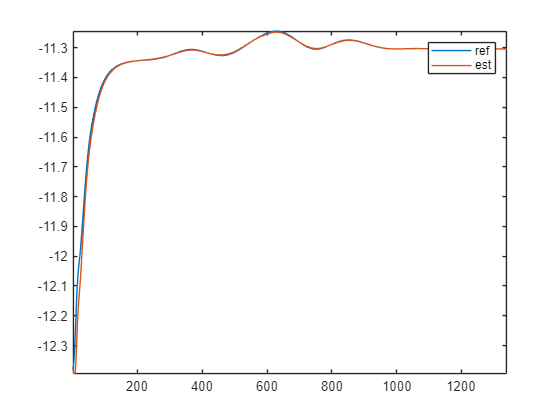

figure;
hold on;
plot(u(:,5));
plot(fvy(q,u,params));
hold off;
axis tight;
box on;
legend('ref','est');

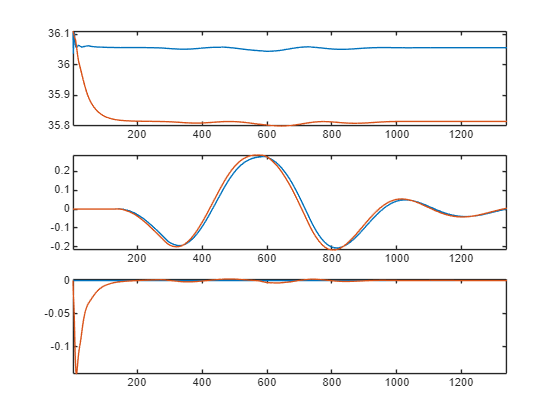

vC = [ref.VxCGC_2,ref.VyCGC_2,0.*ref.Yaw]./3.6;
vCest = fvC(q,u,params);

for k = 1:height(vCest)
    vCest(k,:) = (rotz(rad2deg(yaw(k))).'*vCest(k,:).').';
end

tl = tiledlayout(3,1);
for k = 1:3
    axe = nexttile(tl,k);
    hold(axe,'on');
    plot(vC(:,k));
    plot(vCest(:,k));
    hold(axe,'off');
    box(axe,'on');
    axis(axe,'tight');
end

t = sym('t');
N = Frame;
O = Point;

yaw = DynamicVariable("psi");
camber = DynamicVariable("gamma");
pitch = DynamicVariable("theta");

eul = [
    yaw;
    camber;
    pitch
    ].';

px = DynamicVariable('p_x');
py = DynamicVariable('p_y');
pz = DynamicVariable('p_z');

p = [
    px;
    py;
    pz
    ];

wx = DynamicVariable('omega_x');
wy = DynamicVariable('omega_y');
wz = DynamicVariable('omega_z');
vx = DynamicVariable('v_x');
vy = DynamicVariable('v_y');
vz = DynamicVariable('v_z');

u = [
    wx;
    wy;
    wz;
    vx;
    vy;
    vz
    ];

x = DynamicVariable('x');
y = DynamicVariable('y');

f = sym('f');
cx = sym('c_x');
cy = sym('c_y');

K = [f*eye(2),[cx;cy];0,0,1];
pprint(K)

$$\left[\begin{array}{ccc} f & 0 & c_{x}\\ 0 & f & c_{y}\\ 0 & 0 & 1 \end{array}\right]$$


P = K*[eye(3),zeros(3,1)]*[p.state;1];

pim = [
    x.state;
    y.state;
    ];

pprint(pim);

$$\left[\begin{array}{c} x\\ y \end{array}\right]$$



eqn = pim - P(1:2)./P(3);
pprint(eqn)

$$\left[\begin{array}{c} x-\frac{c_{x}\,p_{z}+f\,p_{x}}{p_{z}}\\ y-\frac{c_{y}\,p_{z}+f\,p_{y}}{p_{z}} \end{array}\right]$$

deqn = diff(eqn,t);
deqn = simplify(expand(deqn));
deqn = nonzeros(deqn);
pprint(deqn);

$$\left[\begin{array}{c} \dot{x}-\frac{f\,{\dot{p}}_{x}}{p_{z}}+\frac{f\,{\dot{p}}_{z}\,p_{x}}{{p_{z}}^{2}}\\ \dot{y}-\frac{f\,{\dot{p}}_{y}}{p_{z}}+\frac{f\,{\dot{p}}_{z}\,p_{y}}{{p_{z}}^{2}} \end{array}\right]$$

w = [
    wx;
    wy;
    wz
    ];

v = [
    vx;
    vy;
    vz
    ];

Ny = N.orientNew('z',yaw.state);
Nc = Ny.orientNew('x',camber.state);
Np = Nc.orientNew('y',pitch.state);

tilt = sym('mu');
Nt = Np.orientNew('y',tilt);
Nb = Nt.orientNew('xy',[-pi/2,pi/2]);

pdot_sub = -(v.state + cross(w.state,p.state));
% pdot_sub = -dcm(Nb)*state(v);
deqn = subs(deqn,p.rate,pdot_sub);
deqn = simplify(expand(deqn));

pprint(deqn);

$$\left[\begin{array}{c} \frac{{p_{z}}^{2}\,\dot{x}+f\,\omega_{y}\,{p_{x}}^{2}+f\,\omega_{y}\,{p_{z}}^{2}-f\,p_{x}\,v_{z}+f\,p_{z}\,v_{x}-f\,\omega_{x}\,p_{x}\,p_{y}-f\,\omega_{z}\,p_{y}\,p_{z}}{{p_{z}}^{2}}\\ \frac{{p_{z}}^{2}\,\dot{y}-f\,\omega_{x}\,{p_{y}}^{2}-f\,\omega_{x}\,{p_{z}}^{2}-f\,p_{y}\,v_{z}+f\,p_{z}\,v_{y}+f\,\omega_{y}\,p_{x}\,p_{y}+f\,\omega_{z}\,p_{x}\,p_{z}}{{p_{z}}^{2}} \end{array}\right]$$

tilt = sym('mu',{'real','positive'});
tr = sym('t_r',{'real','positive'});
rr = sym('rho_r',{'real','positive'});
h = sym('h_c',{'real','positive'});
p = sym('p',{'real','positive'});

params = [
    tilt;
    tr;
    rr;
    p;
    h
    ].';

vy_sub = fvy(eul.state.',u.state.',params);
deqn = subs(deqn,vy.state,vy_sub);
deqn = simplify(expand(deqn));

v = [vx.state,vz.state];

[Mv,fv] = equationsToMatrix(-deqn,v);

vars = {
    f;
    prettify([x.rate,y.rate]);
    prettify([px.state,py.state,pz.state]);
    prettify([yaw.state,camber.state,pitch.state]);
    prettify([wx.state,wy.state,wz.state]);
    params
    }.';

Mv = simplify(expand(Mv));
matlabFunction(prettify(Mv), ...
    'File',"motoEgoMotionMassMatrix", ...
    'Vars',vars);

pprint(Mv);

$$\left[\begin{array}{cc} -\frac{f}{p_{z}} & \frac{f\,p_{x}}{{p_{z}}^{2}}\\ \frac{f\,s_{\gamma }}{c_{\gamma }\,p_{z}\,\cos\left(\mu +\theta \right)} & \frac{f\,\left(p_{y}\,\cos\left(\mu +\theta \right)+p_{z}\,\sin\left(\mu +\theta \right)\right)}{{p_{z}}^{2}\,\cos\left(\mu +\theta \right)} \end{array}\right]$$


fv = simplify(expand(fv));

Ju = jacobian(fv,[x.rate,y.rate]);
Ju = simplify(expand(Ju));
pprint(Ju);

$$\left[\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right]$$


Jw = jacobian(fv,[wx.state,wy.state,wz.state]);
Jw = simplify(expand(Jw));

matlabFunction(prettify(Jw), ...
    'File',"motoEgoMotionAngVelJac", ...
    'Vars',vars);

pprint(Jw);

$$\left[\begin{array}{ccc} -\frac{f\,p_{x}\,p_{y}}{{p_{z}}^{2}} & f+\frac{f\,{p_{x}}^{2}}{{p_{z}}^{2}} & -\frac{f\,p_{y}}{p_{z}}\\ -\frac{f\,\left({p_{y}}^{2}\,\cos\left(\mu +\theta \right)+{p_{z}}^{2}\,\cos\left(\mu +\theta \right)+c_{\theta }\,p\,p_{z}+h_{c}\,p_{z}\,s_{\theta }-p_{z}\,\rho_{r}\,s_{\theta }\right)}{{p_{z}}^{2}\,\cos\left(\mu +\theta \right)} & -\frac{f\,\left(h_{c}\,p_{z}\,s_{\gamma }\,s_{\mu }-c_{\mu }\,p\,p_{z}\,s_{\gamma }-p_{z}\,\rho_{r}\,s_{\gamma }\,s_{\mu }-c_{\gamma }\,c_{\mu }\,c_{\theta }\,p_{x}\,p_{y}+c_{\gamma }\,p_{x}\,p_{y}\,s_{\mu }\,s_{\theta }+c_{\mu }\,p_{z}\,\rho_{r}\,s_{\gamma }\,s_{\theta }+c_{\theta }\,p_{z}\,\rho_{r}\,s_{\gamma }\,s_{\mu }\right)}{c_{\gamma }\,{p_{z}}^{2}\,\cos\left(\mu +\theta \right)} & \frac{f\,\left(c_{\mu }\,h_{c}\,s_{\gamma }-c_{\mu }\,\rho_{r}\,s_{\gamma }+p\,s_{\gamma }\,s_{\mu }+c_{\mu }\,c_{\theta }\,\rho_{r}\,s_{\gamma }-c_{\gamma }\,p_{x}\,s_{\mu }\,s_{\theta }-\rho_{r}\,s_{\gamma }\,s_{\mu }\,s_{\theta }+c_{\gamma }\,c_{\mu }\,c_{\theta }\,p_{x}\right)}{c_{\gamma }\,p_{z}\,\cos\left(\mu +\theta \right)} \end{array}\right]$$